## Problem 4.1--Cubic spline interpolation

**a) Using free run-out boundary conditions, list the curvatures at the sampled points (to  say 2 decimal places). **

% Housekeeping
clear
clc

% Store the data points
x_data=[-1.5 -1.0 -0.5 0 0.5 1.0 1.5];
y_data=cos(x_data);

% Calculate the curvatures
y_dd=curvatures(x_data,y_data)

b_errors = 1.0e-15 *

         0
    0.2220
    0.2220
    0.1110
    0.1110


y_dd =          0
   -0.5711
   -0.8905
   -1.0238
   -0.8905
   -0.5711
         0


**b) Use curvatures obtained in a) to construct a set of piecewise cubic polynomials. Using the cubic piecewise polynomials that correspond to data points in the range [- 1.5,0], graphically show how these behave when extrapolated for -π/2 ≤ x ≤ π/2. **

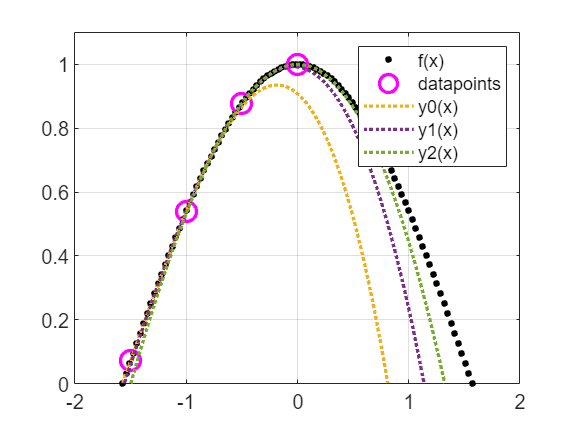

% Housekeeping
figure

% Store the data points
x_data=[-1.5 -1.0 -0.5 0];
y_data=cos(x_data);

% Plot the original function
xint=linspace(-pi/2,pi/2);
plot(xint,cos(xint),'k.')
hold on
% Plot the datapoints
plot(x_data,y_data,'mo')
hold on
% Plot the cubic piecewise polynomials
for n=1:(length(x_data)-1)
    y=cubic_spline(x_data,y_data,y_dd,n,xint);
    plot(xint,y,':')
end
ylim([0,1.1])
hold off
legend('f(x)','datapoints','y0(x)','y1(x)','y2(x)')

**c) For the above curves, compute the 𝐿2 norm of the errors in the function value at the sampled points in the range [-1.5,0].** **The 𝐿2 norm is the vector equivalent of the Frobenius matrix norm introduced in Handout 4.**

% Compute the L2 norm
for n=1:(length(x_data)-1)
    y=cubic_spline(x_data,y_data,y_dd,n,x_data);
    error=y-y_data
    L_2_error = norm(error,2);
    disp(['L_2 norm of errors in y_',num2str(n-1),' at data points =  ', num2str(L_2_error)])
end

error =          0         0   -0.0105   -0.0917


L_2 norm of errors in y_0 at data points =  0.09226


error =    -0.0105         0         0   -0.0078


L_2 norm of errors in y_1 at data points =  0.013042


error =    -0.0725   -0.0078         0         0


L_2 norm of errors in y_2 at data points =  0.072916


**d) Graphically show the cubic spline interpolation result for the range [-1.5,1.5]. Overlay another cubic spline interpolation that utilises only 3 sampled datapoints, i.e. x = -1.5, 0, and 1.5.**

% Housekeeping
clear
clc

% Store the data points
x_7data=[-1.5 -1.0 -0.5 0 0.5 1.0 1.5];
y_7data=cos(x_7data);

% Calculate the curvatures
y_7dd=curvatures(x_7data,y_7data);

b_errors = 1.0e-15 *

         0
    0.2220
    0.2220
    0.1110
    0.1110


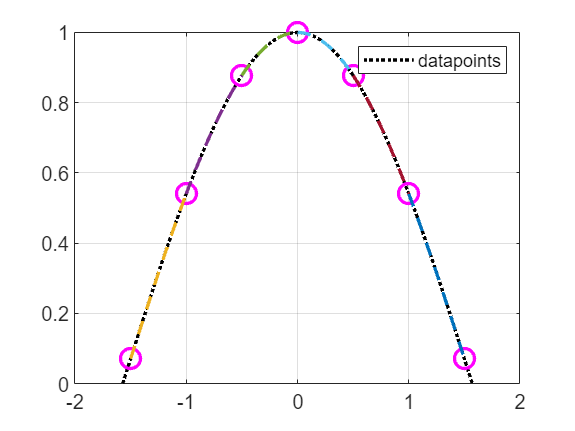


% Plot the original function
xint=linspace(-pi/2,pi/2);
plot(xint,cos(xint),'k:')
hold on
% Plot the datapoints
plot(x_7data,y_7data,'mo')
hold on
% Plot the cubic spline interpolation that utilises only 7 sampled datapoints
for n7=1:(length(x_7data)-1)
    x7=(x_7data(n7):1/1000:x_7data(n7+1));
    y7=cubic_spline(x_7data,y_7data,y_7dd,n7,x7);
    plot(x7,y7,'--')
end
legend('datapoints')
hold off

% Store the data points
x_3data=[-1.5 0 1.5];
y_3data=cos(x_3data);

% Calculate the curvatures
y_3dd=curvatures(x_3data,y_3data);

b_errors = 0

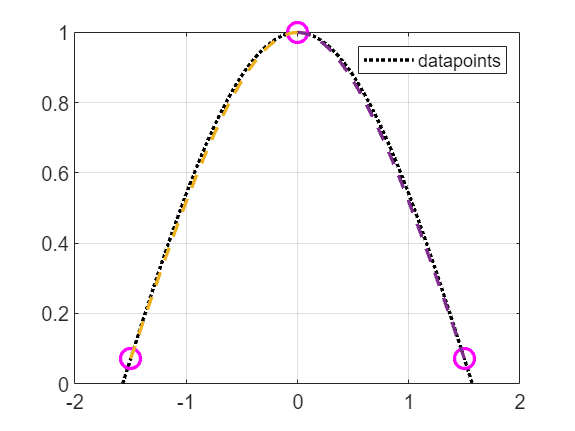


% Plot the original function
xint=linspace(-pi/2,pi/2);
plot(xint,cos(xint),'k:')
hold on
% Plot the datapoints
plot(x_3data,y_3data,'mo')
hold on
% Plot the cubic spline interpolation that utilises only 7 sampled datapoints
for n3=1:(length(x_3data)-1)
    x3=(x_3data(n3):1/1000:x_3data(n3+1));
    y3=cubic_spline(x_3data,y_3data,y_3dd,n3,x3);
    plot(x3,y3,'--')
end
legend('datapoints')
hold off

**e) Briefly comment on why the difference exists. Hint: consider the difference between the approximated and actual second derivatives. Could you use your code for interpolation the following data points x = -1.5, -0.8, -0.25, 0, 0.3, 0.7, 1.5?**

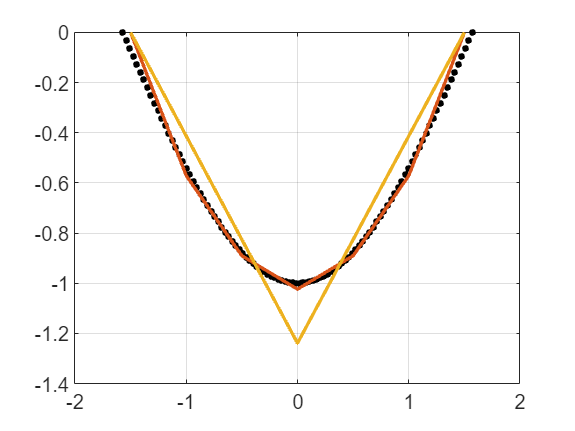

% Plot the original function
xint=linspace(-pi/2,pi/2);
plot(xint,-cos(xint),'k.')
hold on
% Plot the approximate curvature
plot(x_7data,y_7dd)
hold on
plot(x_3data,y_3dd)
hold off

**1) function to calculate the curvature**

function y_dd=curvatures(x_data,y_data)

% Define the delta x
d=x_data(2)-x_data(1);

% Calculate the curvatures
A=zeros(length(x_data)-1-1);
for i=1:(length(x_data)-1-1)
    A(i,i)=2/3;
end

for j=1:(length(x_data)-1-1-1)
    A(j,j+1)=1/6;
end

for k=1+1:(length(x_data)-1-1)
    A(k,k-1)=1/6;
end

for m=1:(length(x_data)-1-1)
    b(m,1)=(y_data(m+2)-2*y_data(m+1)+y_data(m))/(d^2);
end

% A*y_dd=b
y_dd=A\b;

% Checking error of the formula to see if it is big or small
b_errors=abs(b-A*y_dd)

% Output the value
y_dd=[0;y_dd;0];

end

**2) function to calculate the spline polymials**

function y=cubic_spline(x_data,y_data,y_dd,ind,x)

y=...
  (y_dd(ind)/6).*((x_data(ind+1)-x).^3./(x_data(ind+1)-x_data(ind))-(x_data(ind+1)-x_data(ind)).*(x_data(ind+1)-x))+...
  (y_dd(ind+1)/6).*((x-x_data(ind)).^3./(x_data(ind+1)-x_data(ind))-(x_data(ind+1)-x_data(ind)).*(x-x_data(ind)))+...
  y_data(ind).*((x_data(ind+1)-x)./(x_data(ind+1)-x_data(ind)))+...
  y_data(ind+1).*((x-x_data(ind))./(x_data(ind+1)-x_data(ind)));

end